# Feedforward neural network

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

buffer_train = struct with fields:
    X: [22×10000 double]
    Y: [5×10000 double]

buffer_validation = struct with fields:
    X: [22×1000 double]
    Y: [5×1000 double]

ans =           22       10000


Nsamples = 11000

Ninputs = 22

Noutputs = 5

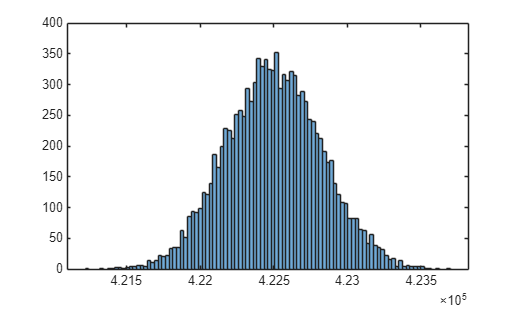

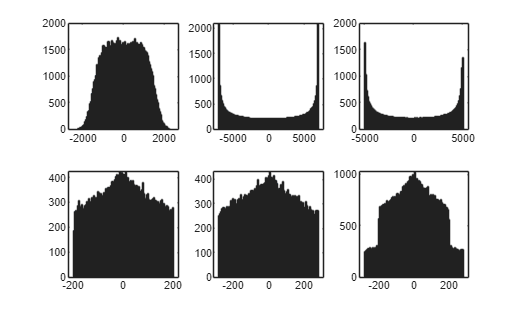

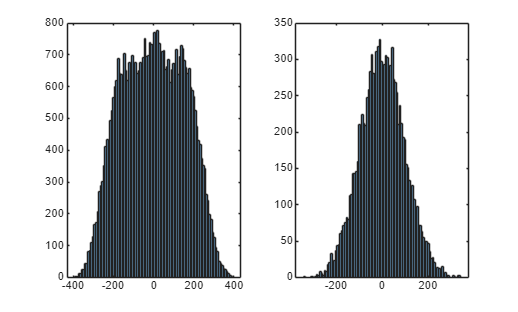

ans = 159.6243

ie_max = 393.8507

ix_max = 200

iy_max = 280

is_max = 250

vo_max = 1000

vB_max = 12000

VCdiff = 0.0020

C = 0.0050

vc_mean_ref = 13000

Xmax = 1.0e+05 *

    4.6475
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0373
    0.0770
    0.0770
    0.0770
    0.0550
    0.0550


Ymax =          500
         500
         500
         500
        1000


ans =           22       11000


ans =            5       11000


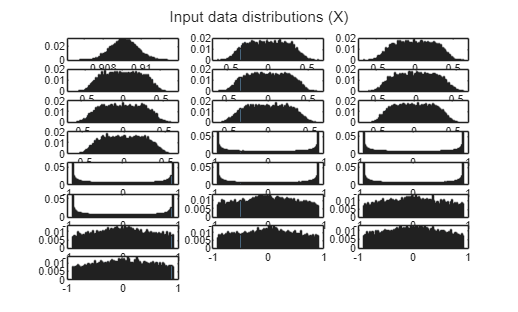

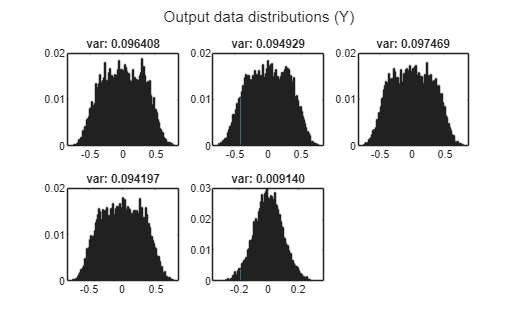

run('DataPreparation.mlx');

save_net = true; % Overwrite current feedforward architecture

## Architecture

argsFFNN                  = struct();
argsFFNN.Ninputs          = Ninputs;
argsFFNN.Noutputs         = Noutputs;
argsFFNN.Nlayers          = 1;
argsFFNN.Nneurons         = 5*Ninputs;
argsFFNN.HiddenActivation = 'relu';
argsFFNN.OutputActivation = 'tanh';
argsFFNN.Dropout          = 0;
argsFFNN.WinitFcn         = 'glorot';
argsFFNN.BinitFcn         = 'glorot';
argsFFNN.BatchNorm        = true;
argsFFNN.TrainBias        = true;

FFnet = FFNNgenerator(argsFFNN)

FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1
  View summary with summary.

## Training

output_variance = var(extractdata(dlY_tr), 0, 2);
var_e = mean(output_variance(1:4));
var_o = output_variance(5);
ErrorWeights = [ones(4, 1); var_e/var_o]

ErrorWeights =     1.0000
    1.0000
    1.0000
    1.0000
   10.4564



argsFFNNtrain                    = struct();
argsFFNNtrain.net                = FFnet;
argsFFNNtrain.X_tr               = dlX_tr;
argsFFNNtrain.Y_tr               = dlY_tr;
argsFFNNtrain.dsXY_tr            = dsXY_tr;
argsFFNNtrain.X_val              = dlX_val;
argsFFNNtrain.Y_val              = dlY_val;
argsFFNNtrain.LearnRateScheduler = "cyclic"; % test, exponential, cyclic, super-convergence
argsFFNNtrain.InitialLearnRate   = 1e-2;
argsFFNNtrain.MaxLearnRate       = 1e-2; % Obtained from the Learn Rate Range Test
argsFFNNtrain.FinalLearnRate     = 1e-5;
argsFFNNtrain.Plots              = 'training-progress'

argsFFNNtrain = struct with fields:
                   net: [1×1 dlnetwork]
                  X_tr: [22×10000 dlarray]
                  Y_tr: [5×10000 dlarray]
               dsXY_tr: [1×1 matlab.io.datastore.CombinedDatastore]
                 X_val: [22×1000 dlarray]
                 Y_val: [5×1000 dlarray]
    LearnRateScheduler: "cyclic"
      InitialLearnRate: 0.0100
          MaxLearnRate: 0.0100
        FinalLearnRate: 1.0000e-05
                 Plots: 'training-progress'

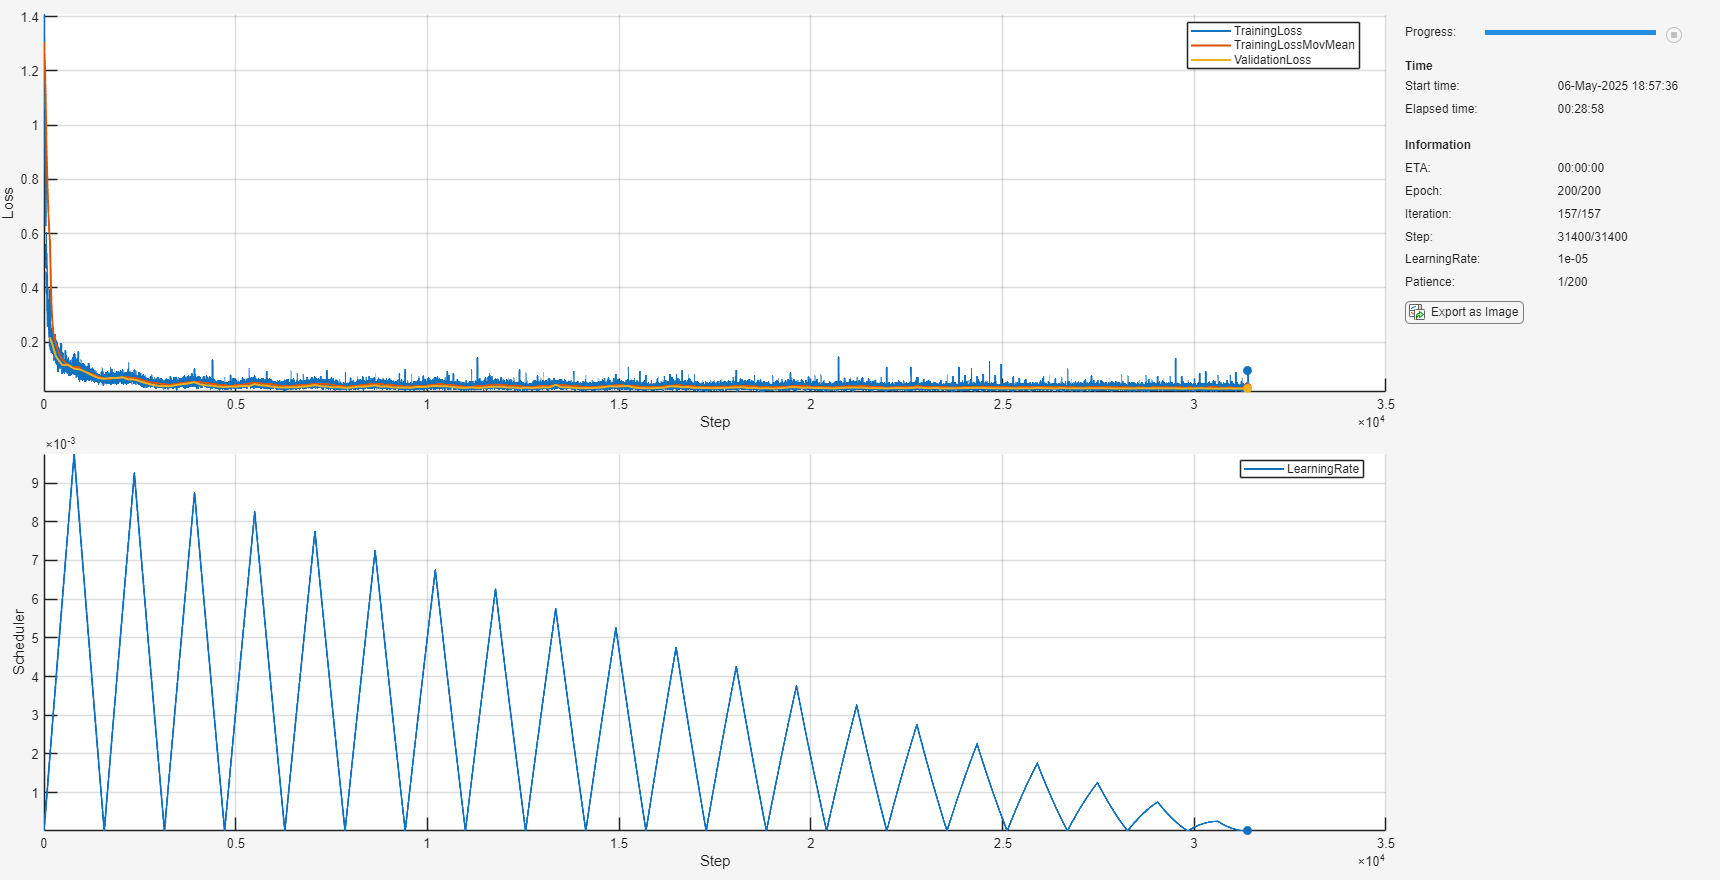

FFnet =   dlnetwork with properties:

         Layers: [7×1 nnet.cnn.layer.Layer]
    Connections: [6×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'tanh'}
    Initialized: 1
  View summary with summary.

argsFFNNtrain.Verbose            = false;
% argsFFNNtrain.MaxEpochs          = 200;
% argsFFNNtrain.MiniBatchSize      = 512;
% argsFFNNtrain.ValidationPatience = 200;
argsFFNNtrain.MaxEpochs          = 200;
argsFFNNtrain.MiniBatchSize      = 64;
argsFFNNtrain.ValidationPatience = 200;
% argsFFNNtrain.MaxEpochs          = 100;
% argsFFNNtrain.MiniBatchSize      = 256;
% argsFFNNtrain.ValidationPatience = 100;
% argsFFNNtrain.MaxEpochs          = 500;
% argsFFNNtrain.MiniBatchSize      = 2048;
% argsFFNNtrain.ValidationPatience = 500;
argsFFNNtrain.HuberThreshold     = 1;
argsFFNNtrain.ErrorWeights       = ErrorWeights;
% 16, 32, 64, 128, 256, 512, 1024
% 
% [FFnet, top10_nets, top10_losses] = Copy_of_FFNNtrain(argsFFNNtrain, 'custom')

FFnet = FFNNtrain(argsFFNNtrain, 'custom')


if save_net
    save('ImitationLearning\ActualArchitecture\FFnet.mat', "FFnet")
end

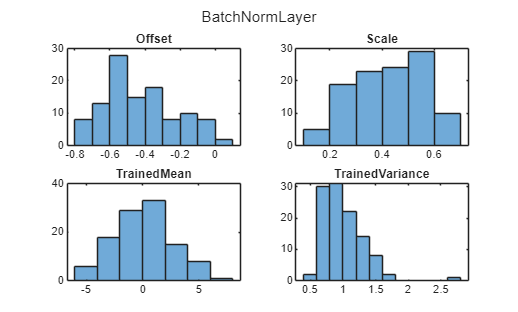

figure
subplot(2, 2, 1)
histogram(FFnet.Layers(3).Offset)
title('Offset')
subplot(2, 2, 2)
histogram(FFnet.Layers(3).Scale)
title('Scale')
subplot(2, 2, 3)
histogram(FFnet.Layers(3).TrainedMean)
title('TrainedMean')
subplot(2, 2, 4)
histogram(FFnet.Layers(3).TrainedVariance)
title('TrainedVariance')
sgtitle('BatchNormLayer')

## Summary

trainPerformance = dlfeval(@FFNNLoss, FFnet, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);
valPerformance   = dlfeval(@FFNNLoss, FFnet, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.020709


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.028797



figure
plot(FFnet)

analyzeNetwork(FFnet);
summary(FFnet)

   Initialized: true
   Number of learnables: 3.3k
   Inputs:
      1   'input'   22 features


# Performance analysis

## Complete timeseries

% pred = extractdata(FFnet.predict(dlX));
% figure
% subplot(ceil(Noutputs/3), 3, 1)
% stairs(1:Nsamples, Y(1, :))
% hold on
% stairs(1:Nsamples, pred(1, :))
% hold off
% for idx = 2:Noutputs
%     subplot(ceil(Noutputs/3), 3, idx)
%     stairs(1:Nsamples, Y(idx, :))
%     hold on
%     stairs(1:Nsamples, pred(idx, :))
%     hold off
% end
% sgtitle('Complete timeseries');

## Error histogram

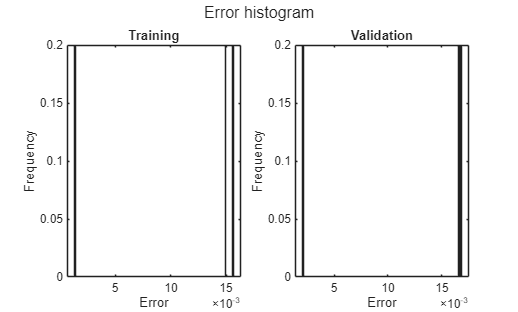

Y_tr_pred = extractdata(FFnet.predict(dlX_tr));
Y_val_pred = extractdata(FFnet.predict(dlX_val));

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 1000, 'Normalization', 'probability')
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 1000, 'Normalization', 'probability')
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

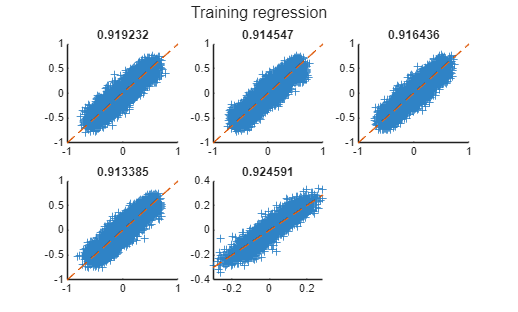

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

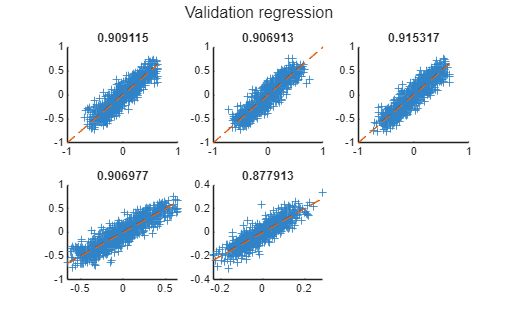


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

Learnables = FFnet.Learnables

Learnables = 6×3 table
       Layer       Parameter          Value      
    ___________    _________    _________________
    "fc_1"         "Weights"    {110×22  dlarray}
    "fc_1"         "Bias"       {110×1   dlarray}
    "batchnorm"    "Offset"     {110×1   dlarray}
    "batchnorm"    "Scale"      {110×1   dlarray}
    "fc_2"         "Weights"    {  5×110 dlarray}
    "fc_2"         "Bias"       {  5×1   dlarray}

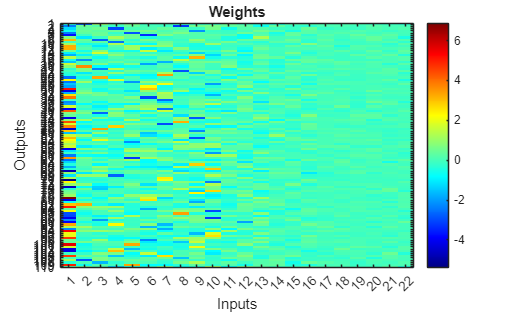

Learnables = Learnables.Value;

weights_input_hidden = extractdata(Learnables{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(abs(weights_input_hidden(:)))

weights_treshold = single
0.0688

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));